## Assignment 02

clear all;
close all;
clc;

format short;

### 0. Introduction

We know that the distribution is an hyper-exponential one. From that we know that the moments are equal to:


$$E[X] = \frac{p_1}{\lambda_1} + \frac{1-p_1}{\lambda_2}$$



$$E[X^2] = 2 \left( \frac{p_1}{\lambda_1^2} + \frac{1-p_1}{\lambda_2^2} \right)$$



$$E[X^3] = 6 \left( \frac{p_1}{\lambda_1^3} + \frac{1-p_1}{\lambda_2^3} \right)$$


From this we can easily apply the *method of moments.*

Moreover the PDF function is:


$$f(t) = p_1 \lambda_1e^{-\lambda_1 t} + (1-p_1)\lambda_2 e^{-\lambda_2 t}$$


And the CDF function is:


$$F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$$


### 1. Load data

T = readtable('data.xlsx');
T.Properties.VariableNames = {'data'};
data = T.data

data = 	1.0e+03 *

    0.0831
    0.0956
    0.1975
    0.0962
    0.4626
    0.0375
    0.4831
    0.1537
    0.0000
    0.0565


N = height(T)

N = 80

### 2. Compute stats

#### 2.1 Moments

First moment

x_1 = (1/N)*sum(data)

x_1 = 220.1726

Second moment

x_2 = (1/N)*sum(data.^2)

x_2 = 1.0562e+05

Third moment

x_3 = (1/N)*sum(data.^3)

x_3 = 7.2900e+07

Fourth moment

x_4 = (1/N)*sum(data.^4)

x_4 = 5.9846e+10

#### 2.2 Compute $\sigma^2$, $\sigma$ and $C_v$

Mean (used for the $C_v$ computation)

mu = mean(data)

mu = 220.1726

Variance

sigma_2_unbiased = var(data)

sigma_2_unbiased = 5.7866e+04

sigma_2 = x_2 - x_1^2

sigma_2 = 5.7143e+04

Standard deviation

sigma_unbiased = sqrt(sigma_2_unbiased)

sigma_unbiased = 240.5536

sigma = sqrt(sigma_2)

sigma = 239.0454

Coefficient of variation

cv = sigma / mu

cv = 1.0857

#### 2.3 Skewness $\gamma$

The skewness is defined as:


$$\gamma = E \left[ \left( \frac{X-\mu}{\sigma} \right)^3 \right] =
\frac{E[X^3] - 2\mu\sigma^2 - \mu^3}{\sigma^3}$$


gamma = (x_3 - 2*mu*sigma_2 - mu^3) ./ (sigma^3)

gamma = 2.7134

gamma_unbiased = skewness(data)

gamma_unbiased = 1.7924

#### 2.4 Kurtois $\beta$


$$\beta= E \left[ \left( \frac{X-\mu}{\sigma} \right)^4 \right] - 3=
\frac{E[(X - \mu)^4]}{\sigma^4} - 3$$


beta = ((1/N) * sum((data - mu).^4)) ./ (sigma^4) - 3

beta = 2.9149

beta_unbiased = kurtosis(data) - 3

beta_unbiased = 2.9149

### 3. Fitting

#### 3.1 Maximum Likelihood method

First we have to compute the likelihood function. So, first let's hyphotesize some valure for $\lambda_1, \lambda_2$ and $p_1$.


$$\lambda_1=0.001$$



$$\lambda_2=0.001$$



$$p_1=0.5$$


l1 = 0.001;
l2 = 0.001;
p1 = 0.5;

So, we have to compute $log(f(t))$

log_pdf = @(data,p1,l1,l2) log10(p1*l1*exp(-l1*data) + (1-p1)*l2*exp(-l2*data));
lpdf = log_pdf(data,p1,l1,l2)

lpdf =    -3.0361
   -3.0415
   -3.0858
   -3.0418
   -3.2009
   -3.0163
   -3.2098
   -3.0668
   -3.0000
   -3.0245


log_likehood = sum(lpdf)

log_likehood = -247.6496

Let's now pass to the maximization procedure:

params = mle(data,'logpdf',log_pdf,'start',[p1,l1,l2], 'Lowerbound', [0, 0, 0], 'Upperbound', [1, 0.1, 0.1])

params =     0.6438    0.0035    0.0092


**Note that: **in order to allow the *mle *procedure to converge we need to set a "good" starting point (obtained thinking of the meaning of the three parameters) and the bounds (set by thinking of significant parameters for the hyperexpoenential distribution).

Let's evaluate the fit:

p1_ml = params(1)

p1_ml = 0.6438

l1_ml = params(2)

l1_ml = 0.0035

l2_ml = params(3)

l2_ml = 0.0092

fitted_log_likelihood = sum(log_pdf(data,p1_ml,l1_ml,l2_ml))

fitted_log_likelihood = -221.8616

Approximating CDF:

sorted_data = sort(data)

sorted_data = 	1.0e+03 *

    0.0000
    0.0091
    0.0092
    0.0096
    0.0172
    0.0173
    0.0242
    0.0271
    0.0282
    0.0302


t = 1/80:1/80:1

t =     0.0125    0.0250    0.0375    0.0500    0.0625    0.0750    0.0875    0.1000    0.1125    0.1250    0.1375    0.1500    0.1625    0.1750    0.1875    0.2000    0.2125    0.2250    0.2375    0.2500    0.2625    0.2750    0.2875    0.3000    0.3125    0.3250    0.3375    0.3500    0.3625    0.3750    0.3875    0.4000    0.4125    0.4250    0.4375    0.4500    0.4625    0.4750    0.4875    0.5000    0.5125    0.5250    0.5375    0.5500    0.5625    0.5750    0.5875    0.6000    0.6125    0.6250


figure();
plot(sorted_data, t, 'LineWidth', 2);
grid on;
hold on;

Let's now compare it with the analytical $F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$:

F_ml = @(t) 1 - p1_ml*exp(-l1_ml*t) - (1-p1_ml)*exp(-l2_ml*t);
cdf_data_ml = F_ml(sorted_data)

cdf_data_ml =     0.0002
    0.0491
    0.0495
    0.0519
    0.0904
    0.0907
    0.1242
    0.1378
    0.1428
    0.1516


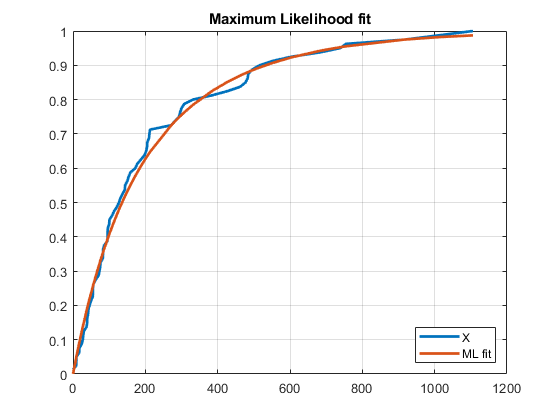

plot(sorted_data, cdf_data_ml, 'LineWidth', 2);
hold off;
legend({'X','ML fit'},'Location','southeast');
title('Maximum Likelihood fit');

#### 3.2 Method of moments

Recalling the moments of an hyper-exponential distribution:


$$E[X] = \frac{p_1}{\lambda_1} + \frac{1-p_1}{\lambda_2}$$



$$E[X^2] = 2 \left( \frac{p_1}{\lambda_1^2} + \frac{1-p_1}{\lambda_2^2} \right)$$



$$E[X^3] = 6 \left( \frac{p_1}{\lambda_1^3} + \frac{1-p_1}{\lambda_2^3} \right)$$


x_1

x_1 = 220.1726

x_2

x_2 = 1.0562e+05

x_3

x_3 = 7.2900e+07

So, we have to solve the system of 3 equations in 3 unknowns:

F = @(x) [x(1)/x(2) + (1-x(1))/x(3) - x_1;
          2*(x(1)/(x(2)^2) + (1-x(1))/(x(3)^2)) - x_2;
          6*(x(1)/(x(2)^3) + (1-x(1))/(x(3)^3)) - x_3];

x0 = [0.5;0.001;0.001];
options = optimoptions('fsolve','Display','iter','FunctionTolerance',1e-18);
[x,fval] = fsolve(F,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          4     3.51305e+19                      5.33e+22               1
     1          8     6.15785e+18    0.000465691       7.15e+21               1
     2         12     1.05703e+18    0.000608765       9.65e+20               1
     3         16     1.72588e+17    0.000774644       1.32e+20               1
     4         20     2.49693e+16    0.000925399       1.85e+19               1
     5         24     2.67981e+15    0.000955458       2.66e+18               1
     6         25     2.67981e+15              1       2.66e+18               1
     7         26     2.67981e+15           0.25       2.66e+18            0.25
     8         27     2.67981e+15         0.0625       2.66e+18          0.0625
     9         28     2.67981e+15       0.015625       2.66e+18          0.0156
    10         32     1.34526e+14    0.0007

x =     0.4999
    0.0043
    0.0043


fval =     9.7200
   82.5765
   -0.0798


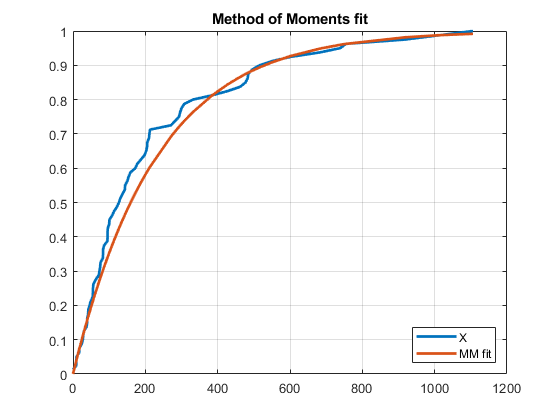

p1_mm = x(1);
l1_mm = x(2);
l2_mm = x(3);

F_mm = @(t) 1 - p1_mm*exp(-l1_mm*t) - (1-p1_mm)*exp(-l2_mm*t);
cdf_data_mm = F_mm(sorted_data);

figure();
plot(sorted_data, t, 'LineWidth', 2);
hold on;
plot(sorted_data, cdf_data_mm, 'LineWidth', 2);
grid on;
hold off;
legend({'X','MM fit'},'Location','southeast');
title('Method of Moments fit');

#### 6.3 Maximum Likelihook & Method of Moments - CDF comparison

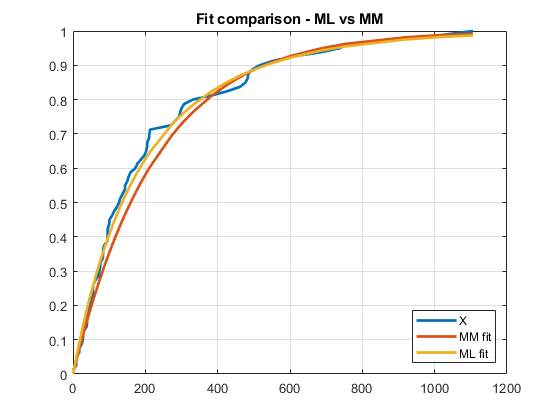

figure();

plot(sorted_data, t, 'LineWidth', 2);
hold on;
plot(sorted_data, cdf_data_mm, 'LineWidth', 2);
hold on;
plot(sorted_data, cdf_data_ml, 'LineWidth', 2);
grid on;
hold off;

legend({'X','MM fit','ML fit'},'Location','southeast');
title('Fit comparison - ML vs MM');

#### 6.4 Maximum Likelihook & Method of Moments - P-P Plots

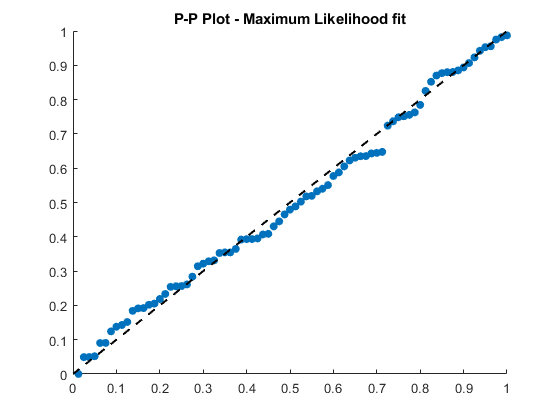

figure();
s = scatter(t, cdf_data_ml);
s.Marker = 'o';
s.MarkerFaceColor = 'flat';
s.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;

hold off;
title('P-P Plot - Maximum Likelihood fit');

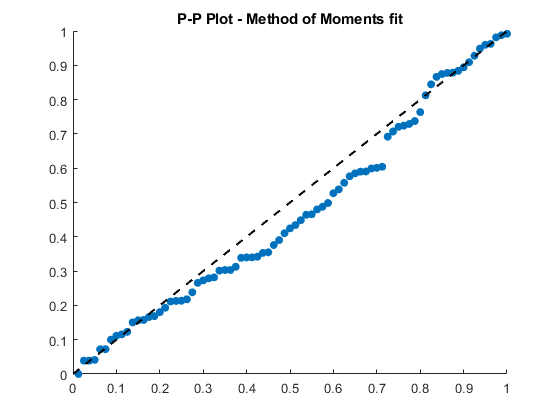

figure();
s = scatter(t, cdf_data_mm);
s.Marker = 'o';
s.MarkerFaceColor = 'flat';
s.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;

hold off;
title('P-P Plot - Method of Moments fit');

**Combined P-P Plots**

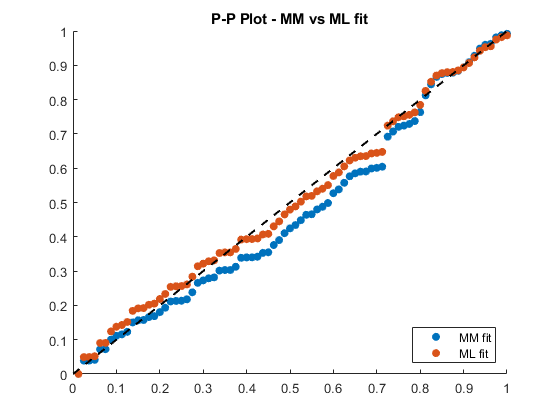

figure();
s1 = scatter(t, cdf_data_mm);
s1.Marker = 'o';
s1.MarkerFaceColor = 'flat';
s1.MarkerEdgeColor = 'none';
hold on;
s2 = scatter(t, cdf_data_ml);
s2.Marker = 'o';
s2.MarkerFaceColor = 'flat';
s2.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;

hold off;
legend({'MM fit','ML fit'},'Location','southeast');
title('P-P Plot - MM vs ML fit');

#### 6.5 Maximum Likelihook & Method of Moments - Q-Q Plots

We have to compare the distribution of the first half of the samples, with the second half.

data_1 = sort(data(1:40))

data_1 =     0.0401
    9.1873
    9.6423
   17.2908
   24.2404
   30.1575
   37.4712
   39.1659
   39.3886
   49.3430


data_2 = sort(data(41:80))

data_2 = 	1.0e+03 *

    0.0091
    0.0172
    0.0271
    0.0282
    0.0417
    0.0425
    0.0457
    0.0625
    0.0710
    0.0761


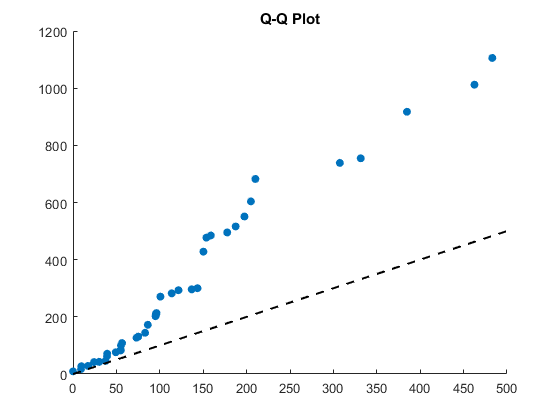

figure();
s = scatter(data_1, data_2);
s.Marker = 'o';
s.MarkerFaceColor = 'flat';
s.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;
hold off;
title('Q-Q Plot');

We note from the Q-Q plot that the distribution doesn't fit the $y=x$ line, maybe because the dataset is small, since 80 samples may be not enough to achieve a good result.